# Analysis of the connection of two pipes

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_3_pipes_r_1_5mm');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_3_pipes_r_1_5mm


#### Parameters

%call to the parameters file
Parameters

### Assigning constants

%assigning the pressure value
p0=p_syringe

p0 = 0.0070

%viscosity
mu=mu_Water

mu = 9.9792e-04

%diffusion
D_coeff=D_NaOH

D_coeff = 5.3000e-09

#### Flow rate for a given pressure drop  

**Description:** This block assumes a syringe is connected to the inlet of the pipe and introduces a constant flow rate Q. The pressure formula follows the Hagen–Poiseuille equation [1, Eq. (3.1)  pp. 43 and Table 3.1 pp.47]

$\Delta P=\frac{8\mu L Q}{\pi r^4}$, (1)

where 

$\mu$ is the water viscosity,

$L$ is the channel length,

$r$ is the radius of the pipe.

% Q_nL_per_min=10;
% Q=Q_nL_per_min*10^(-9)*10^(-3)/60;
% Delta_P=(8*mu_Water*L_outer)/(pi*radius_cylinder_1^4)*Q
% Delta_P_mmHg=Delta_P/133.322
%flow rate in [m^3/s]
Q_m3_s=p0*(pi*r_vec.^4)/(8*mu*l_vec(end));
%flow rate in [uL/min]
Q_uL_m=Q_m3_s*60/(1e-6*1e-3);
disp(['Min Q_ul_m=',num2str(min(Q_uL_m))])

Min Q_ul_m=3.1295


disp(['Max Q_ul_m=',num2str(max(Q_uL_m))])

Max Q_ul_m=6.9837


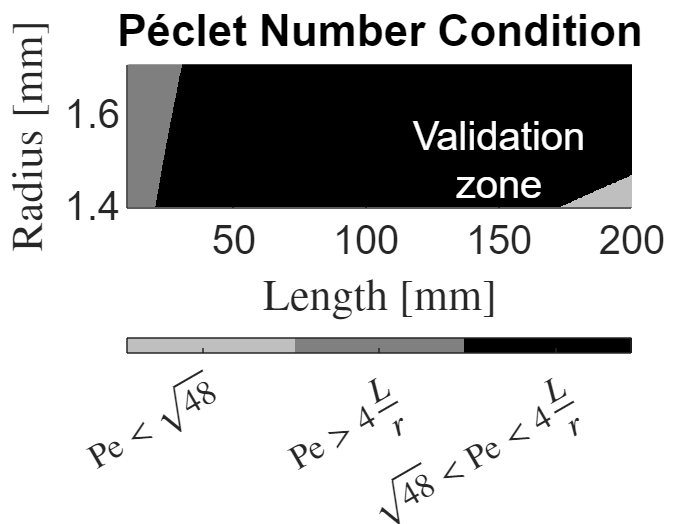


%flow rate in [uL/h]
Q_uL_h=Q_m3_s*60*60/(1e-6*1e-3);

#### Peak time and peak amplitude vs radius and length

% operating on the permisible range
total_points=100;
r_vec=linspace(1.612,1.7,total_points)*1e-3;%radius cilinder
l_vec=linspace(30.5,40,total_points)*1e-3;%length of the pipe

%defining the time interval
total_points=1e3;
time_ini=115;
time_end=200;
time_vector = linspace(time_ini,time_end,total_points);

syms t

peak_amp=zeros(length(r_vec),length(l_vec));
peak_tau=zeros(length(r_vec),length(l_vec));

tic;
for i_r=1:length(r_vec)

    i_r/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Evaluating the mean velocity [2, pag. 54]
        v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l));

        %Evaluating the Effective Diffusion
        %[1, Eq.(4.54) pp.77]
        D_eff=r_vec(i_r)^2*v_char^2/48/D_coeff;

        %Validating the diffusion within the pipe
        %Evaluation of the Péclet number, this evaluation follows [1,Eq. (4.44) pp.75]
        Pe=r_vec(i_r)*v_char/D_coeff;

        if(Pe>4*l_vec(i_l)/r_vec(i_r))            
            disp(['Concentration is not constant along the x-axis, Pe=',num2str(Pe),' is larger than ',num2str(4*l_vec(i_l)/r_vec(i_r))])
            i_l
            i_r
        end

        if(Pe<sqrt(48))            
            disp(['Diffusion hasn''t occurred along the axis, Pe=',num2str(Pe),' is less than ',num2str(sqrt(48))])
            i_l
            i_r
        end

        %Evaluating the concentration of the straigth channel
        c=1./2.*erfc((l_vec(i_l)-v_char*t)./(2*sqrt(D_eff*t)));
        %Evaluating the channel impulse response
        h=diff(c,t);

        % %for testing purposes only
        % figure;plot(time_vector,subs(h,time_vector)); grid on;

        %Looking for the maximum of the channel impulse response with the first derivative
        h_diff=diff(h,t);
        %Evaluating the derivative with time
        obj_fcn_time=double(subs(h_diff, t, time_vector));

        % %for testing purposes
        % figure;plot(time_vector,obj_fcn_time);

        %Evaluating the time interval where the first derivative is zero
        [~, max_time] = max(obj_fcn_time);
        [~, min_time] = min(obj_fcn_time);
        
        % %for testing purposes
        % time_vector(max_time)
        % time_vector(min_time)
        
        %looking for the peak time and peak amplitude
        peak_tau(i_r,i_l)=vpasolve(h_diff,t,[time_vector(max_time),time_vector(min_time)]);
        peak_amp(i_r,i_l)=subs(h, t, peak_tau(i_r,i_l));
    end
end

ans = 5

ans = 10

ans = 15

ans = 20

ans = 25

ans = 30

ans = 35

ans = 40

ans = 45

ans = 50

ans = 55.0000

ans = 60

ans = 65

ans = 70

ans = 75

ans = 80

ans = 85

ans = 90

ans = 95

ans = 100

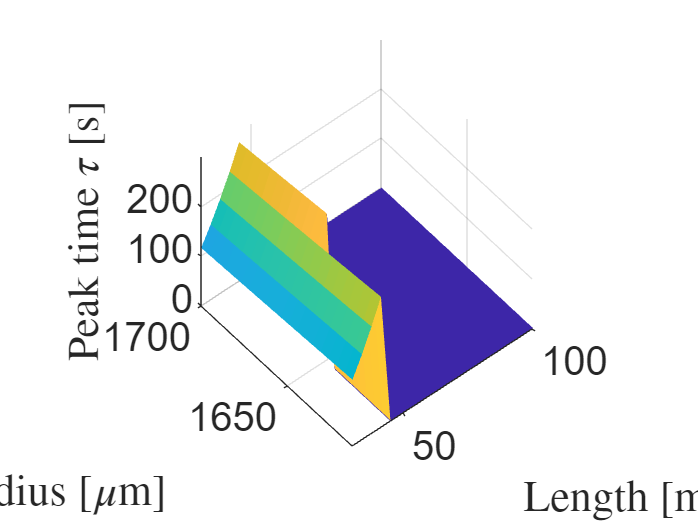

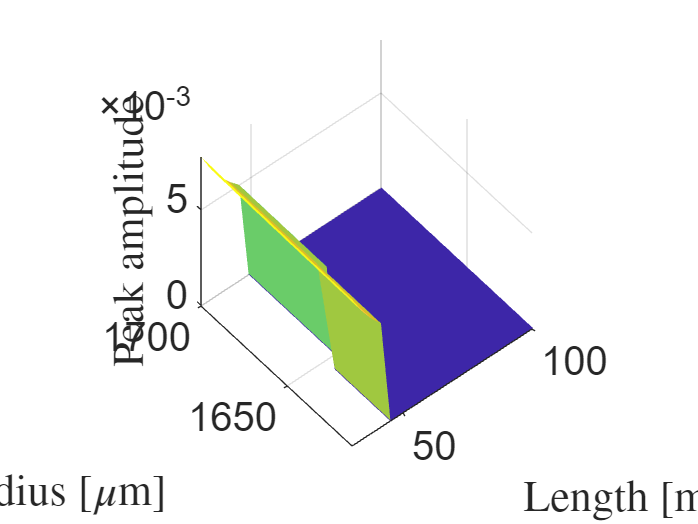

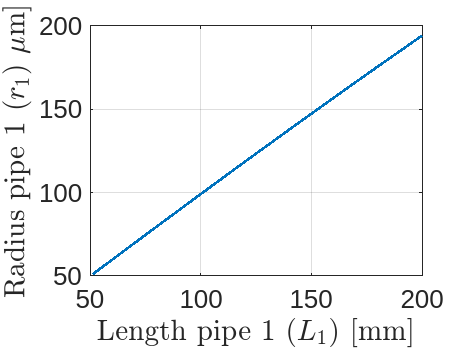

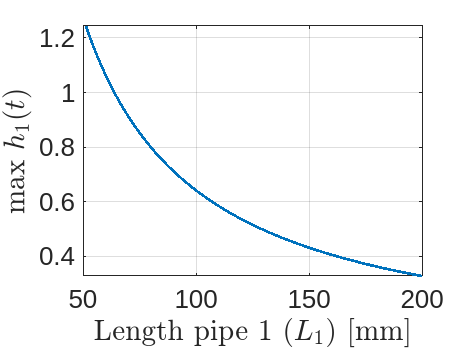

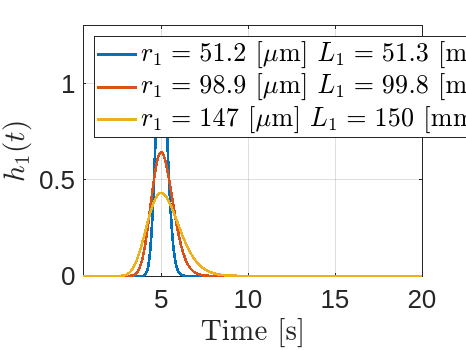

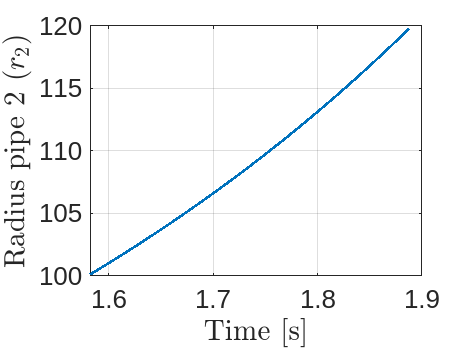

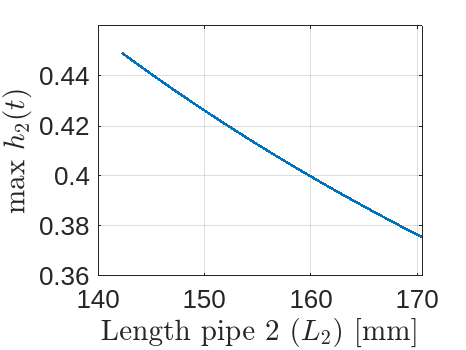

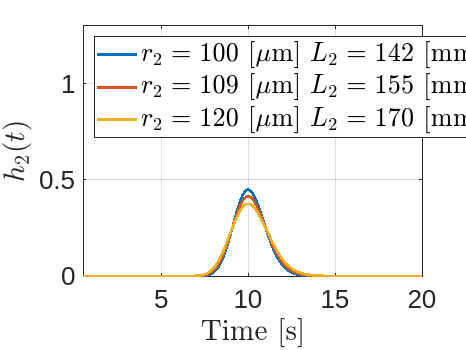

ans = 5

ans = 10

ans = 15

ans = 20

ans = 25

ans = 30

ans = 35

ans = 40

ans = 45

ans = 50

ans = 55.0000

ans = 60

ans = 65

ans = 70

ans = 75

ans = 80

ans = 85

ans = 90

ans = 95

ans = 100

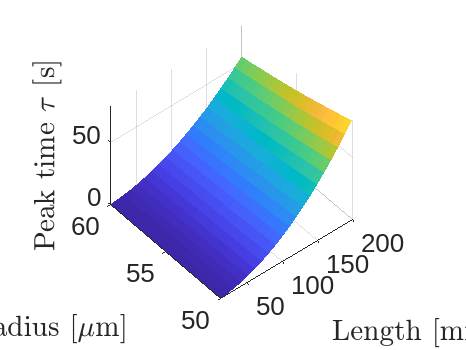

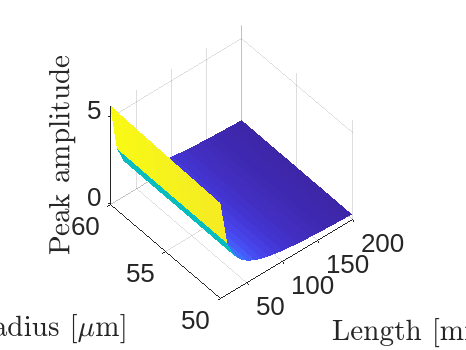

toc;

%Saving results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

% Save the results into the specified folder
save(fullfile(outputFolder, 'tau_vs_r_l.mat') ,'peak_tau','peak_amp','p0','mu', 'time_vector','l_vec','r_vec');

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] J. Crank. 1986. The Mathematics of Diffusion. Oxford University Press.

[4] A. B. Carlson, P. B. Crilly, and J. C. Rutledge, Communication Systems: An Introduction to Signals and Noise in Electrical Communication, 4th ed. New York City, NY: McGraw-Hill, 2002, p. 850.

[5] R. Chang, *Chemistry*. Boston, Mass.: McGraw-Hill Education, 1998.  